# Linear Regression

## Introduction

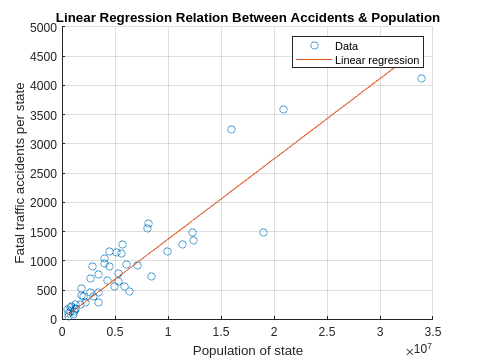

load accidents
x = hwydata(:,14); %Population of states
y = hwydata(:,4); %Accidents per state
format long
b1 = x\y;
yCalc1 = b1*x;
scatter(x,y)
hold on
plot(x,yCalc1)
xlabel('Population of state')
ylabel('Fatal traffic accidents per state')
title('Linear Regression Relation Between Accidents & Population')
legend('Data','Linear regression')
grid on
hold off

# SVD visualization

M = [0.5, 1; 0.5, 0.5];
[U, S, V] = svd(M)

U =   -0.850650808352040  -0.525731112119134
  -0.525731112119133   0.850650808352040


S =    1.309016994374947                   0
                   0   0.190983005625053


V =   -0.525731112119134   0.850650808352040
  -0.850650808352040  -0.525731112119134



subplot(2,3,1)
plot([0 0], [0 1], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 1], [0 0], 'b', 'LineWidth',3)

subplot(2,3,2)
v1 = M*[0;1]

v1 =    1.000000000000000
   0.500000000000000


v2 = M*[1;0]

v2 =    0.500000000000000
   0.500000000000000


plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

subplot(2,3,3)
v1 = M*[0;1]

v1 =    1.000000000000000
   0.500000000000000


v2 = M*[1;0]

v2 =    0.500000000000000
   0.500000000000000


plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

subplot(2,3,4)
v1 = V'*[0;1]

v1 =   -0.850650808352040
  -0.525731112119134


v2 = V'*[1;0]

v2 =   -0.525731112119134
   0.850650808352040


plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

subplot(2,3,5)
v1 = S*V'*[0;1]*S(1,1)

v1 =   -1.457611844529399
  -0.131432778029783


v2 = S*V'*[1;0]*S(2,2)

v2 =   -0.131432778029783
   0.031027070086670


plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

subplot(2,3,6)
v1 = U*S*V'*[0;1]

v1 =    0.999999999999999
   0.500000000000000


v2 = U*S*V'*[1;0]

v2 =    0.500000000000000
   0.500000000000000


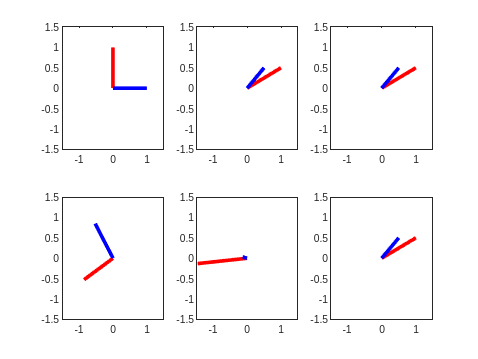

plot([0 v1(1)], [0 v1(2)], 'r', 'LineWidth',3)
hold on
xlim([-1.5,1.5])
ylim([-1.5,1.5])
plot([0 v2(1)], [0 v2(2)], 'b', 'LineWidth',3)
hold off

### Danger #1: not enough info in X

x=[1,1,1,1,2,1,2,1,3,2,2,3,2,2,3,7,9]';
z=5*[1,2,4,3,6,4,5,5,4,2,2,1,7,7,8,2,1]';
X = [ones(length(x),1) x]

X =      1     1
     1     1
     1     1
     1     1
     1     2
     1     1
     1     2
     1     1
     1     3
     1     2


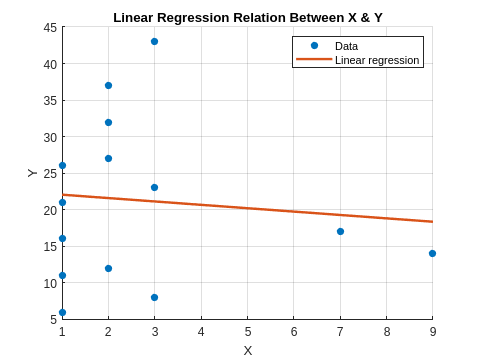

y=x+z;
b1 = X\y;
yCalc1 = X*b1;
figure;
scatter(x,y,'filled')
hold on 
plot(x,yCalc1,'LineWidth',2)
xlabel('X')
ylabel('Y')
title('Linear Regression Relation Between X & Y')
legend('Data','Linear regression')
grid on
hold off

### Danger #2: Y=f(X), f not linear

x=linspace(1,5,15)'

x =    1.000000000000000
   1.285714285714286
   1.571428571428571
   1.857142857142857
   2.142857142857143
   2.428571428571429
   2.714285714285714
   3.000000000000000
   3.285714285714286
   3.571428571428572


X = [ones(length(x),1) x]

X =    1.000000000000000   1.000000000000000
   1.000000000000000   1.285714285714286
   1.000000000000000   1.571428571428571
   1.000000000000000   1.857142857142857
   1.000000000000000   2.142857142857143
   1.000000000000000   2.428571428571429
   1.000000000000000   2.714285714285714
   1.000000000000000   3.000000000000000
   1.000000000000000   3.285714285714286
   1.000000000000000   3.571428571428572


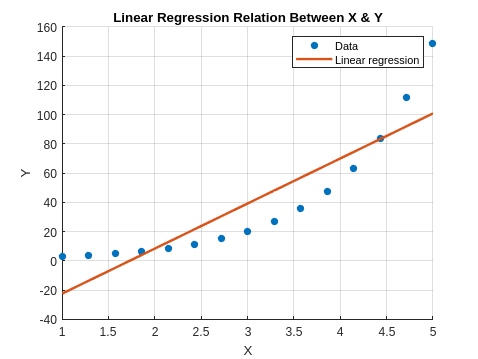

y=exp(x);
b1 = X\y;
yCalc1 = X*b1;
figure;

scatter(x,y,'filled')
hold on 
plot(x,yCalc1,'LineWidth',2)
xlabel('X')
ylabel('Y')
title('Linear Regression Relation Between X & Y')
legend('Data','Linear regression')
grid on
hold off

### Danger #3: outliers

x=[1,2,3,4,5,6,7,8,9,10]'

x =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


X = [ones(length(x),1) x]

X =      1     1
     1     2
     1     3
     1     4
     1     5
     1     6
     1     7
     1     8
     1     9
     1    10


y=40-3*x

y =     37
    34
    31
    28
    25
    22
    19
    16
    13
    10


y(9)=45

y =     37
    34
    31
    28
    25
    22
    19
    16
    45
    10


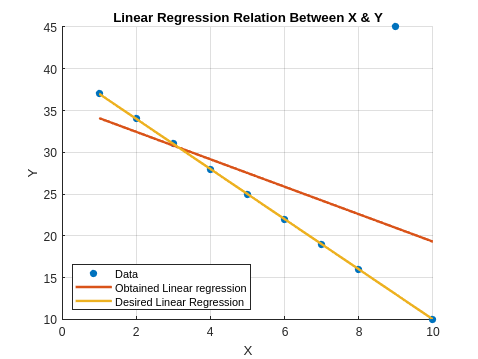

z=40-3*x;
b1 = X\y;
b2 = X\z;
yCalc1 = X*b1;
yCalc2 = X*b2;
figure;
scatter(x,y,'filled')
hold on 
plot(x,yCalc1,'LineWidth',2)
plot(x,yCalc2,'LineWidth',2)
xlabel('X')
ylabel('Y')
title('Linear Regression Relation Between X & Y')
legend('Data','Obtained Linear regression','Desired Linear Regression','Location','southwest')
grid on
hold off

# Probabilistic approach

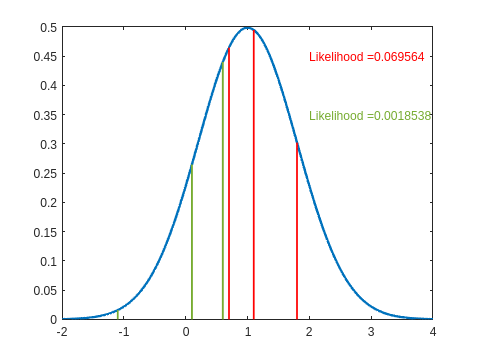

mu=1;
sigma=0.8;
figure;
x=linspace(-2,4,500);
plot(x,normpdf(x,mu,sigma), 'color', [0 0.4470 0.7410], 'LineWidth',2)
D=[1.1,0.7,1.8];
hold on
plot([D(1),D(1)],[0,normpdf(D(1),mu,sigma)], 'r', 'LineWidth',1.5)
plot([D(2),D(2)],[0,normpdf(D(2),mu,sigma)], 'r', 'LineWidth',1.5)
plot([D(3),D(3)],[0,normpdf(D(3),mu,sigma)], 'r', 'LineWidth',1.5)
txt = strcat('Likelihood = ',string(prod(normpdf(D,mu,sigma))));
text(2,0.45,txt,'Color','red')
D=[0.1,0.6,-1.1];
hold on
plot([D(1),D(1)],[0,normpdf(D(1),mu,sigma)], 'color', [0.4660 0.6740 0.1880], 'LineWidth',1.5)
plot([D(2),D(2)],[0,normpdf(D(2),mu,sigma)], 'color', [0.4660 0.6740 0.1880], 'LineWidth',1.5)
plot([D(3),D(3)],[0,normpdf(D(3),mu,sigma)], 'color', [0.4660 0.6740 0.1880], 'LineWidth',1.5)
txt = strcat('Likelihood = ',string(prod(normpdf(D,mu,sigma))));
text(2,0.35,txt,'color', [0.4660 0.6740 0.1880])
hold off

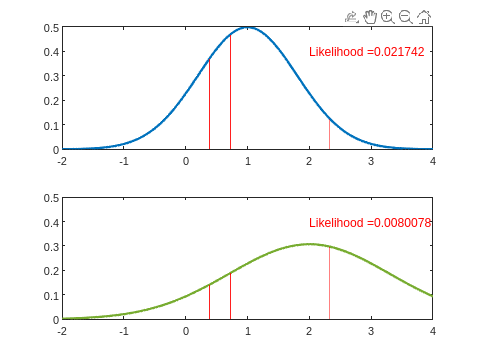

mu_2=2;
sigma_2=1.3;
figure;
rng(5);
data=normrnd(mu,sigma,3,1);

subplot(2,1,1)
plot(x,normpdf(x,mu,sigma), 'color', [0 0.4470 0.7410], 'LineWidth',2)
hold on
for i = 1:length(data)
    plot([data(i),data(i)],[0,normpdf(data(i),mu,sigma)], 'r')
end
txt = strcat('Likelihood = ',string(prod(normpdf(data,mu,sigma))));
text(2,0.4,txt,'color','red')
hold off

subplot(2,1,2)
plot(x,normpdf(x,mu_2,sigma_2), 'color', [0.4660 0.6740 0.1880], 'LineWidth',2)
ylim([0 0.5])
hold on
for i = 1:length(data)
    plot([data(i),data(i)],[0,normpdf(data(i),mu_2,sigma_2)], 'r')
end
txt = strcat('Likelihood = ',string(prod(normpdf(data,mu_2,sigma_2))));
text(2,0.4,txt,'color','red')
hold off